close all
clear variables

fd = 100;
t = 0:1/fd:5;
fs = 1

fs = 1

f = sign(sin(2*fs*pi*t));

fg = figure

fg =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 378 560 420]
       Units: 'pixels'

  Show all properties


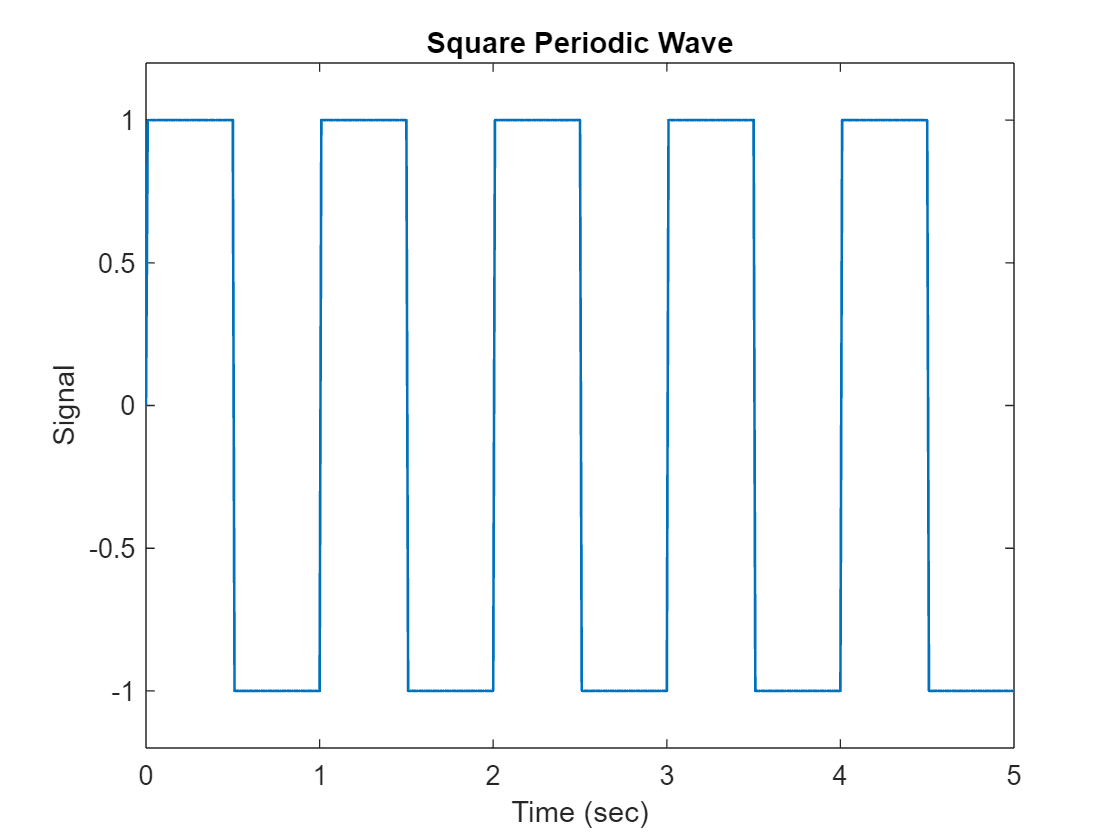

plot(t, f, 'LineWidth', 1)
axis([0 5 -1.2 1.2])
xlabel("Time (sec)")
ylabel("Signal")
title("Square Periodic Wave")
saveas(fg, 'lab_4-spectr\meandr.png')

N_sint = 10

N_sint = 10

f_sint = zeros(1, length(t))

f_sint =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



for i = 1 : length(t)
    total = 0;
    for j = 1 : N_sint
        total = total + sin(2*fs*pi*(2*j - 1) * t(i)) / (2*j - 1);
    end
    f_sint(i) = 4/pi * total;
end

fg1 = figure

fg1 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 378 560 420]
       Units: 'pixels'

  Show all properties


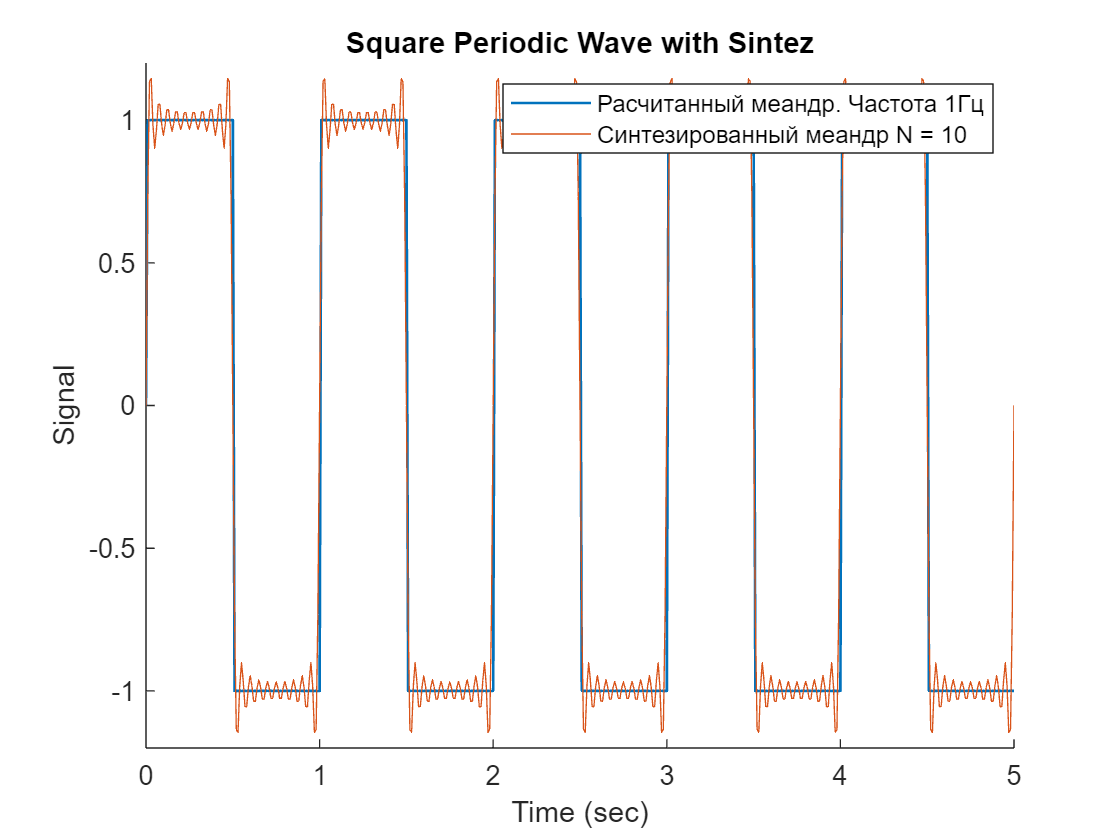

hold all
plot(t, f, 'LineWidth', 1)
plot(t, f_sint)
legend('Расчитанный меандр. Частота 1Гц', 'Синтезированный меандр N = 10')
hold off
axis([0 5 -1.2 1.2])
xlabel("Time (sec)")
ylabel("Signal")
title("Square Periodic Wave with Sintez")
saveas(fg1, 'lab_4-spectr\meandr_with_sintez.png')

N_harm = 8

N_harm = 8

f_harm = zeros(1, length(t))

f_harm =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



fg2 = figure

fg2 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 378 560 420]
       Units: 'pixels'

  Show all properties


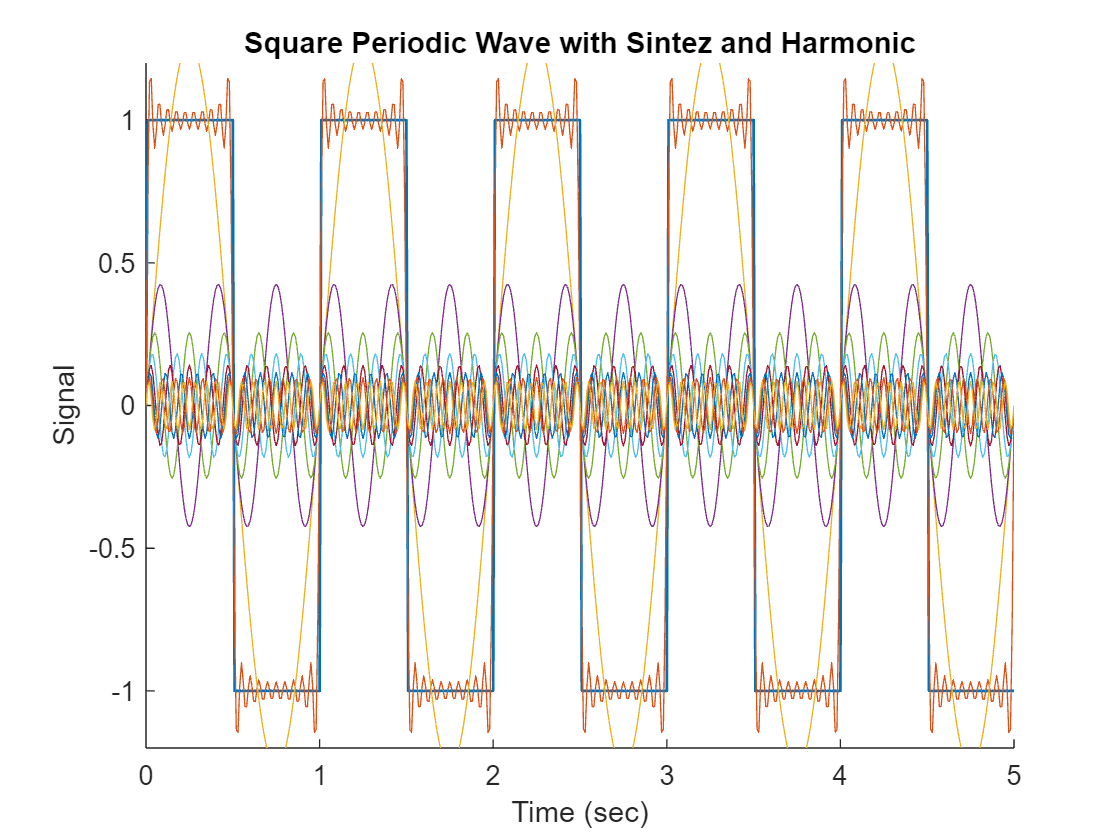

hold all
plot(t, f, 'LineWidth', 1)
plot(t, f_sint)
for j = 1 : N_harm
    for i = 1 : length(t)
        f_harm(i) = 4/pi * sin(2*fs*pi*(2*j - 1) * t(i)) / (2*j - 1);
    end
    plot(t, f_harm)
end
hold off
axis([0 5 -1.2 1.2])
xlabel("Time (sec)")
ylabel("Signal")
title("Square Periodic Wave with Sintez and Harmonic")
saveas(fg2, 'lab_4-spectr\meandr_with_sintez_harmonic.png')

fg3 = figure

fg3 =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 378 560 420]
       Units: 'pixels'

  Show all properties



df0 = fd / length(f);
fk0 = 0 : df0 : fd/2 - df0

fk0 =          0    0.1996    0.3992    0.5988    0.7984    0.9980    1.1976    1.3972    1.5968    1.7964    1.9960    2.1956    2.3952    2.5948    2.7944    2.9940    3.1936    3.3932    3.5928    3.7924    3.9920    4.1916    4.3912    4.5908    4.7904    4.9900    5.1896    5.3892    5.5888    5.7884    5.9880    6.1876    6.3872    6.5868    6.7864    6.9860    7.1856    7.3852    7.5848    7.7844    7.9840    8.1836    8.3832    8.5828    8.7824    8.9820    9.1816    9.3812    9.5808    9.7804


X_meandr0 = fft(f)

X_meandr0 = 1.0e+02 *

   0.0000 + 0.0000i  -0.0000 - 0.0032i  -0.0000 - 0.0072i  -0.0000 - 0.0137i   0.0000 - 0.0305i   0.0000 - 3.1895i  -0.0000 + 0.0312i   0.0000 + 0.0139i   0.0000 + 0.0073i  -0.0000 + 0.0033i  -0.0000 + 0.0001i   0.0000 - 0.0032i   0.0000 - 0.0072i   0.0000 - 0.0135i  -0.0000 - 0.0299i   0.0000 - 1.0631i  -0.0000 + 0.0319i   0.0000 + 0.0141i   0.0000 + 0.0074i  -0.0000 + 0.0034i   0.0000 + 0.0001i  -0.0000 - 0.0031i   0.0000 - 0.0071i  -0.0000 - 0.0134i   0.0000 - 0.0293i  -0.0000 - 0.6378i  -0.0000 + 0.0326i   0.0000 + 0.0143i   0.0000 + 0.0075i  -0.0000 + 0.0035i  -0.0000 + 0.0002i  -0.0000 - 0.0030i  -0.0000 - 0.0070i  -0.0000 - 0.0132i  -0.0000 - 0.0287i   0.0000 - 0.4556i  -0.0000 + 0.0333i  -0.0000 + 0.0145i  -0.0000 + 0.0076i   0.0000 + 0.0035i   0.0000 + 0.0003i  -0.0000 - 0.0030i  -0.0000 - 0.0069i   0.0000 - 0.0130i   0.0000 - 0.0281i   0.0000 - 0.3543i  -0.0000 + 0.0341i   0.0000 + 0.0147i   0.0000 + 0.0077i  -0.0000 + 0.0036i


X0 = abs(X_meandr0(1, 1 : length(fk0))) / length(fk0)

X0 =          0    0.0013    0.0029    0.0055    0.0122    1.2758    0.0125    0.0056    0.0029    0.0013    0.0000    0.0013    0.0029    0.0054    0.0120    0.4252    0.0127    0.0056    0.0030    0.0014    0.0001    0.0012    0.0028    0.0053    0.0117    0.2551    0.0130    0.0057    0.0030    0.0014    0.0001    0.0012    0.0028    0.0053    0.0115    0.1822    0.0133    0.0058    0.0031    0.0014    0.0001    0.0012    0.0027    0.0052    0.0112    0.1417    0.0136    0.0059    0.0031    0.0014



df = fd / length(f_sint);
fk = 0 : df : fd/2 - df

fk =          0    0.1996    0.3992    0.5988    0.7984    0.9980    1.1976    1.3972    1.5968    1.7964    1.9960    2.1956    2.3952    2.5948    2.7944    2.9940    3.1936    3.3932    3.5928    3.7924    3.9920    4.1916    4.3912    4.5908    4.7904    4.9900    5.1896    5.3892    5.5888    5.7884    5.9880    6.1876    6.3872    6.5868    6.7864    6.9860    7.1856    7.3852    7.5848    7.7844    7.9840    8.1836    8.3832    8.5828    8.7824    8.9820    9.1816    9.3812    9.5808    9.7804


X_meandr = fft(f_sint)

X_meandr = 1.0e+02 *

   0.0000 + 0.0000i   0.0000 - 0.0032i   0.0001 - 0.0071i   0.0003 - 0.0135i   0.0008 - 0.0302i   0.1000 - 3.1870i  -0.0012 + 0.0316i  -0.0006 + 0.0144i  -0.0004 + 0.0079i  -0.0002 + 0.0040i  -0.0000 + 0.0008i   0.0002 - 0.0024i   0.0005 - 0.0063i   0.0010 - 0.0125i   0.0025 - 0.0287i   0.0996 - 1.0558i  -0.0033 + 0.0328i  -0.0016 + 0.0152i  -0.0010 + 0.0087i  -0.0006 + 0.0047i  -0.0002 + 0.0016i   0.0002 - 0.0016i   0.0007 - 0.0054i   0.0017 - 0.0115i   0.0041 - 0.0271i   0.0989 - 0.6256i  -0.0056 + 0.0339i  -0.0027 + 0.0159i  -0.0017 + 0.0094i  -0.0010 + 0.0055i  -0.0004 + 0.0024i   0.0001 - 0.0007i   0.0009 - 0.0045i   0.0022 - 0.0104i   0.0055 - 0.0254i   0.0978 - 0.4385i  -0.0080 + 0.0348i  -0.0039 + 0.0166i  -0.0025 + 0.0101i  -0.0016 + 0.0062i  -0.0008 + 0.0031i  -0.0000 + 0.0001i   0.0009 - 0.0035i   0.0026 - 0.0093i   0.0067 - 0.0235i   0.0964 - 0.3325i  -0.0106 + 0.0356i  -0.0052 + 0.0173i  -0.0033 + 0.0108i  -0.0022 + 0.0070i


X = abs(X_meandr(1, 1 : length(fk))) / length(fk)

X =     0.0000    0.0013    0.0028    0.0054    0.0121    1.2754    0.0126    0.0058    0.0032    0.0016    0.0003    0.0010    0.0025    0.0050    0.0115    0.4242    0.0132    0.0061    0.0035    0.0019    0.0006    0.0006    0.0022    0.0047    0.0110    0.2534    0.0137    0.0065    0.0038    0.0022    0.0010    0.0003    0.0018    0.0043    0.0104    0.1797    0.0143    0.0068    0.0042    0.0026    0.0013    0.0001    0.0015    0.0038    0.0098    0.1385    0.0148    0.0072    0.0045    0.0029


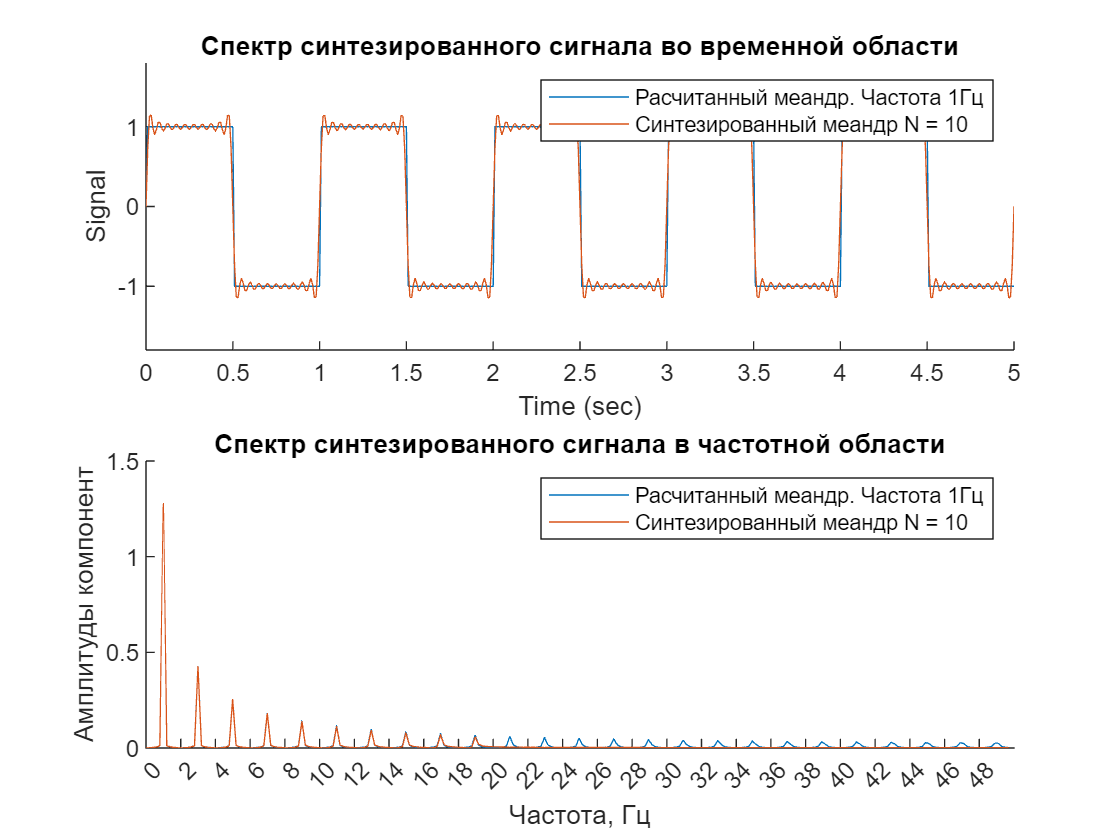


subplot(2, 1, 1)
hold all
plot(t, f)
plot(t, f_sint)
hold off
axis([0 5 -1.8 1.8])
title("Спектр синтезированного сигнала во временной области")
xlabel("Time (sec)")
ylabel("Signal")
legend('Расчитанный меандр. Частота 1Гц', 'Синтезированный меандр N = 10')

subplot(2, 1, 2)
hold all
plot(fk0, X0)
plot(fk, X)
hold off
xlabel('Частота, Гц');
ylabel('Амплитуды компонент');
title("Спектр синтезированного сигнала в частотной области")
xticks([0: 2 :(fd/2)-df])
legend('Расчитанный меандр. Частота 1Гц', 'Синтезированный меандр N = 10')

fg4 = figure

fg4 =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 378 560 420]
       Units: 'pixels'

  Show all properties


X_a = awgn(f_sint, 10)

X_a =     0.1700    1.3131    0.4206    1.4180    1.0836    0.4876    0.8274    1.1631    2.1875    1.8619    0.5196    1.9417    1.2653    1.0163    1.2149    0.8960    0.9480    1.4998    1.4744    1.4382    1.1790    0.6076    1.2528    1.5415    1.1449    1.2954    1.2201    0.9301    1.1189    0.7405    1.2476    0.6274    0.6908    0.7727    0.0562    1.4157    1.0917    0.7975    1.4692    0.4407    0.9141    0.9098    1.1568    1.1537    0.6911    0.8916    0.9307    1.3439    1.4807    1.0840



df_1 = fd / length(X_a);
fk_1 = 0 : df_1 : fd/2 - df_1

fk_1 =          0    0.1996    0.3992    0.5988    0.7984    0.9980    1.1976    1.3972    1.5968    1.7964    1.9960    2.1956    2.3952    2.5948    2.7944    2.9940    3.1936    3.3932    3.5928    3.7924    3.9920    4.1916    4.3912    4.5908    4.7904    4.9900    5.1896    5.3892    5.5888    5.7884    5.9880    6.1876    6.3872    6.5868    6.7864    6.9860    7.1856    7.3852    7.5848    7.7844    7.9840    8.1836    8.3832    8.5828    8.7824    8.9820    9.1816    9.3812    9.5808    9.7804


X_a_meander = fft(X_a)

X_a_meander = 1.0e+02 *

  -0.0349 + 0.0000i   0.0871 - 0.0035i   0.0696 - 0.0137i   0.0187 - 0.0566i   0.0321 - 0.0383i   0.1639 - 3.1676i   0.0343 - 0.0595i   0.0398 + 0.0372i   0.0426 - 0.0346i  -0.0017 - 0.0231i  -0.0085 - 0.0570i  -0.0666 - 0.0310i  -0.0294 - 0.0333i   0.0330 - 0.0889i  -0.0686 - 0.0347i  -0.0196 - 1.0747i   0.0698 + 0.0218i  -0.0474 + 0.0418i   0.0350 + 0.0321i  -0.0582 + 0.0174i  -0.0081 - 0.0342i   0.0119 + 0.0540i   0.0091 + 0.0825i  -0.0187 - 0.0195i  -0.0726 - 0.0405i   0.1486 - 0.7479i   0.0248 - 0.0061i  -0.0547 + 0.0275i  -0.0165 + 0.0123i  -0.0074 + 0.0522i  -0.0682 - 0.0272i  -0.0543 + 0.0036i  -0.0478 - 0.0271i   0.0902 - 0.0383i   0.0365 - 0.0398i   0.0447 - 0.3789i   0.0099 + 0.1123i   0.0466 + 0.0821i  -0.0638 - 0.0399i   0.0570 + 0.0673i  -0.0432 + 0.0707i   0.0067 + 0.0143i  -0.0251 + 0.0727i   0.0963 - 0.0366i  -0.0124 - 0.0858i   0.0417 - 0.3739i  -0.0027 + 0.0365i  -0.0814 - 0.0043i   0.1411 + 0.0617i   0.0455 + 0.0322i


X_f = abs(X_a_meander(1, 1 : length(fk_1))) / length(fk_1)

X_f =     0.0140    0.0349    0.0284    0.0239    0.0200    1.2687    0.0275    0.0218    0.0220    0.0092    0.0230    0.0294    0.0178    0.0379    0.0308    0.4299    0.0293    0.0253    0.0190    0.0243    0.0141    0.0221    0.0332    0.0108    0.0333    0.3050    0.0102    0.0245    0.0082    0.0211    0.0294    0.0218    0.0220    0.0392    0.0216    0.1526    0.0451    0.0377    0.0301    0.0353    0.0331    0.0063    0.0308    0.0412    0.0347    0.1505    0.0147    0.0326    0.0616    0.0223


fg5 = figure

fg5 =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 378 560 420]
       Units: 'pixels'

  Show all properties



X_a_sr = meanfilt(transpose(X_a), 5)

X_a_sr =     0.4488    0.6984    0.8811    0.9446    0.8475    0.9960    1.1499    1.3055    1.3119    1.5348    1.5552    1.3210    1.1916    1.2668    1.0681    1.1150    1.2066    1.2513    1.3079    1.2398    1.1904    1.2038    1.1452    1.1685    1.2909    1.2264    1.1419    1.0610    1.0514    0.9329    0.8850    0.8158    0.6789    0.7126    0.8054    0.8268    0.9661    1.0430    0.9427    0.9063    0.9781    0.9150    0.9651    0.9606    0.9648    1.0022    1.0676    1.1462    0.9132    0.5853



df_2 = fd / length(X_a);
fk_2 = 0 : df_2 : fd/2 - df_2

fk_2 =          0    0.1996    0.3992    0.5988    0.7984    0.9980    1.1976    1.3972    1.5968    1.7964    1.9960    2.1956    2.3952    2.5948    2.7944    2.9940    3.1936    3.3932    3.5928    3.7924    3.9920    4.1916    4.3912    4.5908    4.7904    4.9900    5.1896    5.3892    5.5888    5.7884    5.9880    6.1876    6.3872    6.5868    6.7864    6.9860    7.1856    7.3852    7.5848    7.7844    7.9840    8.1836    8.3832    8.5828    8.7824    8.9820    9.1816    9.3812    9.5808    9.7804


X_a_meander_sr = fft(X_a_sr)

X_a_meander_sr = 1.0e+02 *

  -0.0363 + 0.0000i   0.0857 - 0.0036i   0.0681 - 0.0138i   0.0173 - 0.0567i   0.0306 - 0.0384i   0.1619 - 3.1554i   0.0327 - 0.0595i   0.0381 + 0.0365i   0.0408 - 0.0347i  -0.0031 - 0.0232i  -0.0098 - 0.0566i  -0.0668 - 0.0310i  -0.0301 - 0.0332i   0.0308 - 0.0873i  -0.0679 - 0.0344i  -0.0202 - 1.0378i   0.0657 + 0.0201i  -0.0466 + 0.0391i   0.0319 + 0.0295i  -0.0562 + 0.0155i  -0.0089 - 0.0331i   0.0098 + 0.0492i   0.0072 + 0.0752i  -0.0184 - 0.0192i  -0.0674 - 0.0382i   0.1332 - 0.6777i   0.0211 - 0.0068i  -0.0498 + 0.0231i  -0.0157 + 0.0094i  -0.0076 + 0.0441i  -0.0600 - 0.0250i  -0.0475 + 0.0015i  -0.0416 - 0.0246i   0.0744 - 0.0338i   0.0291 - 0.0347i   0.0355 - 0.3115i   0.0070 + 0.0889i   0.0362 + 0.0636i  -0.0511 - 0.0333i   0.0433 + 0.0503i  -0.0340 + 0.0522i   0.0042 + 0.0087i  -0.0195 + 0.0520i   0.0697 - 0.0289i  -0.0098 - 0.0640i   0.0288 - 0.2673i  -0.0026 + 0.0232i  -0.0565 - 0.0052i   0.0943 + 0.0392i   0.0294 + 0.0190i


X_f_sr = abs(X_a_meander_sr(1, 1 : length(fk_2))) / length(fk_2)

X_f_sr =     0.0145    0.0343    0.0278    0.0237    0.0196    1.2638    0.0272    0.0211    0.0214    0.0094    0.0230    0.0294    0.0179    0.0370    0.0304    0.4152    0.0275    0.0243    0.0174    0.0233    0.0137    0.0201    0.0302    0.0106    0.0310    0.2763    0.0088    0.0220    0.0073    0.0179    0.0260    0.0190    0.0193    0.0327    0.0181    0.1254    0.0357    0.0293    0.0244    0.0266    0.0249    0.0039    0.0222    0.0302    0.0259    0.1075    0.0094    0.0227    0.0409    0.0140


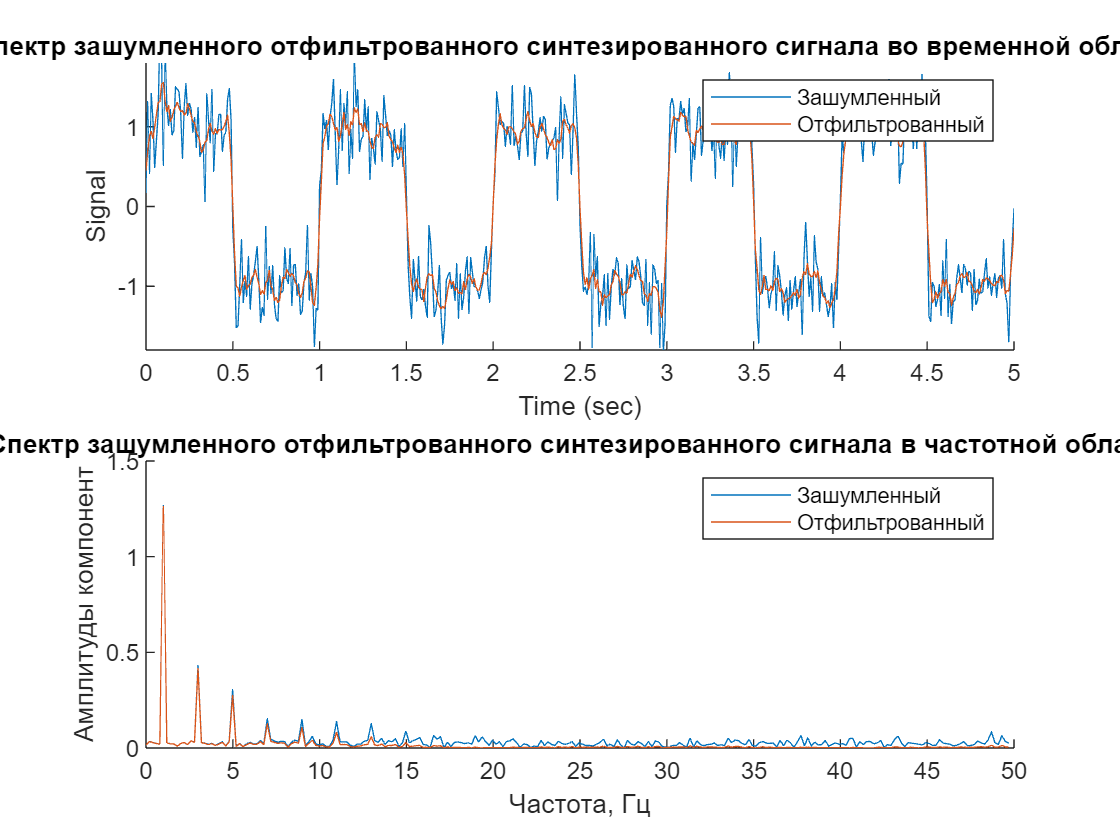


subplot(2, 1, 1)
hold all
plot(t, X_a)
plot(t, X_a_sr)
hold off
axis([0 5 -1.8 1.8])
title("Спектр зашумленного отфильтрованного синтезированного сигнала во временной области")
xlabel("Time (sec)")
ylabel("Signal")
legend('Зашумленный', 'Отфильтрованный')

subplot(2, 1, 2)
hold all
plot(fk_1, X_f)
plot(fk_1, X_f_sr)
hold off
title("Спектр зашумленного отфильтрованного синтезированного сигнала в частотной области")
xlabel('Частота, Гц');
ylabel('Амплитуды компонент');
legend('Зашумленный', 'Отфильтрованный')

function y = meanfilt(x, N)
    y = zeros(1, length(x));
    x = apdate(x, N);
    for i = 1 : (length(x) - (N - 1))
        y(i) = sum(x(i:i+(N-1)))/N;
    end
end

function x_new = apdate(x, N)
    if mod(N-1, 2) == 0
        for i = 1 : (N-1)/2
            x = [x(1, 1); x];
        end
        for i = 1 : (N-1)/2
            x = [x; x(length(x), 1)];
        end
    else
        for i = 1 : (N)/2
            x = [x(1, 1); x];
        end
        for i = 1 : (N-2)/2
            x = [x; x(length(x), 1)];
        end
    end
    x_new = x;
end